# PROPRIOPERCEPTIVE SENSORS

% ACCURACY: DISTANCE BETWEEN PERFORMED AND IDEAL RESPONSE TO A GIVEN INPUT 
% REPEATABILITY: CAPABILITY TO REPRODUCE SAME OUTPUT FOR GIVEN INPUT
% STABILITY: CAPABILITY TO KEEP SAME RESPONSE TO SAME INPUT OVER TIME/TEMPERATURE
% LINEARITY ERROR: MAX DEVIATION OF OUTPUT FROM STRAIGHT LINE
% OFFSET ERROR: OUTPUT VALUE FROM ZERO INPUT
% RESOLUTION ERROR: MAX INPUT VARIATION THAT PRODUCES NO VARIATION OF OUTPUT

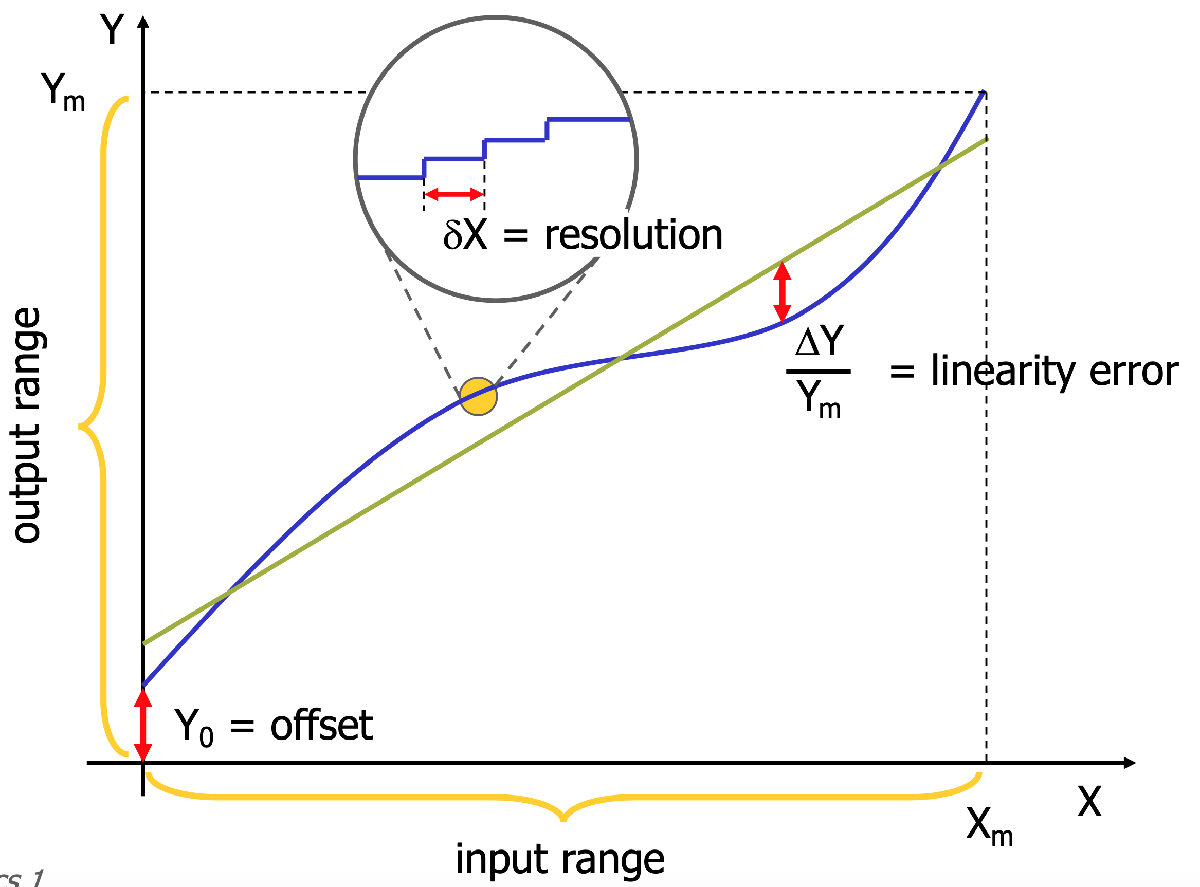

INCREMENTAL ENCODER (POSITION)

syms Ne % tracks or electrical resolution are generally 2000
Ne=2000 % incremental encoder optical disk tracks/resolution per turn

Ne = 2000

resol_incremental= 360/Ne % mechanical resolution per turn

resol_incremental = 0.1800

ABSOLUTE ENCODER (POSITION)

syms n resol_absolute
n=12 % number of bits/tracks

n = 12

steps =2^n % steps per resolution

steps = 4096

resol_absolute= 360/steps % resolution of unit variation

resol_absolute = 0.0879

TACHOMETER (VELOCITY)

syms coil_mass magnet_flux % tachometer

coil_mass=3 % [Kg]

coil_mass = 3

magnet_flux=10 % [(Kg*m^2)/(s^2*A)] [V*s]

magnet_flux = 10

numb_coils=4

numb_coils = 4

phase_shift=180/numb_coils

phase_shift = 45

ACCELEROMETER (ACCELERATION)

syms M K D Kt % accelerometer
M=0.1

M = 0.1000

K=20

K = 20

D=2.5

D = 2.5000

Kt=1

Kt = 1

F=tf([Kt*M],[M D K])


F =
 
          0.1
  --------------------
  0.1 s^2 + 2.5 s + 20
 
Continuous-time transfer function.



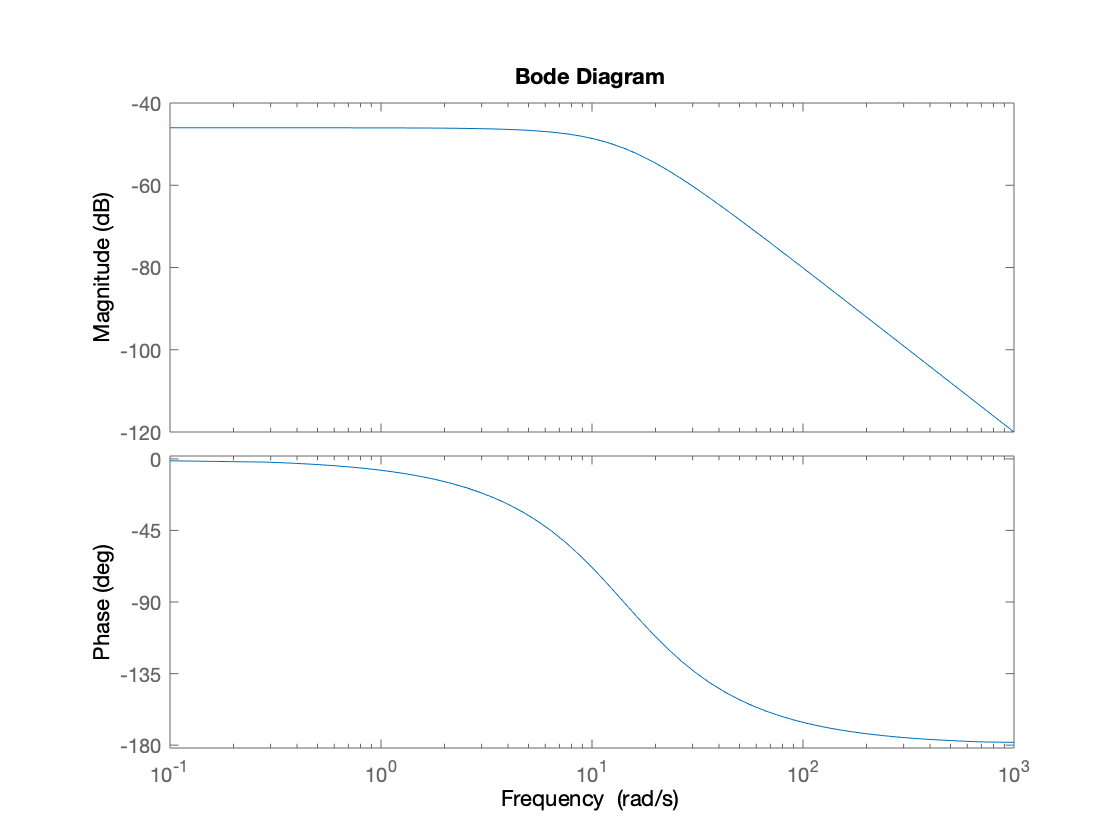

bode(F)

# EXTEROPERCEPTIVE SENSORS

STRAIN GAUGES (FORCE/TORQUE) - ARM

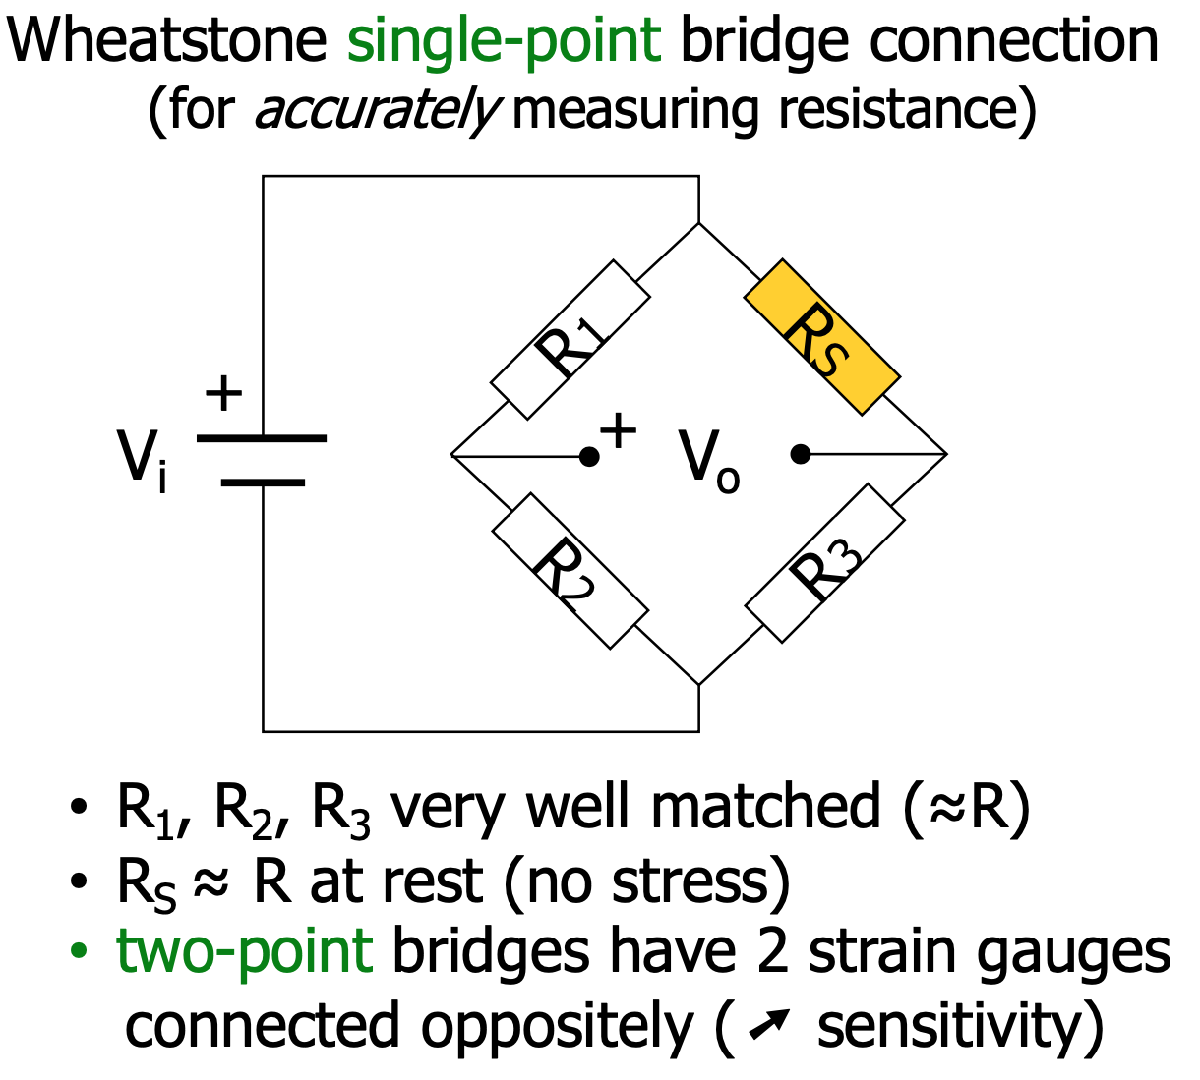

syms Vi Vo R1 R2 R3 Rs % strain gauges

Vo=(R2/(R1+R2)-R3/(R3+Rs))*Vi

$$Vo = \mathrm{Vi}\,\left(\frac{R_{2}}{R_{1}+R_{2}}-\frac{R_{3}}{R_{3}+\mathrm{Rs}}\right)$$


syms R L GF % gauge factor

GF=(diff(R)/R)/(diff(L)/L) % diff(L)/L) is strain epsilon

$$GF = \frac{L}{R}$$

6D (FORCE/TORQUE) - WRIST

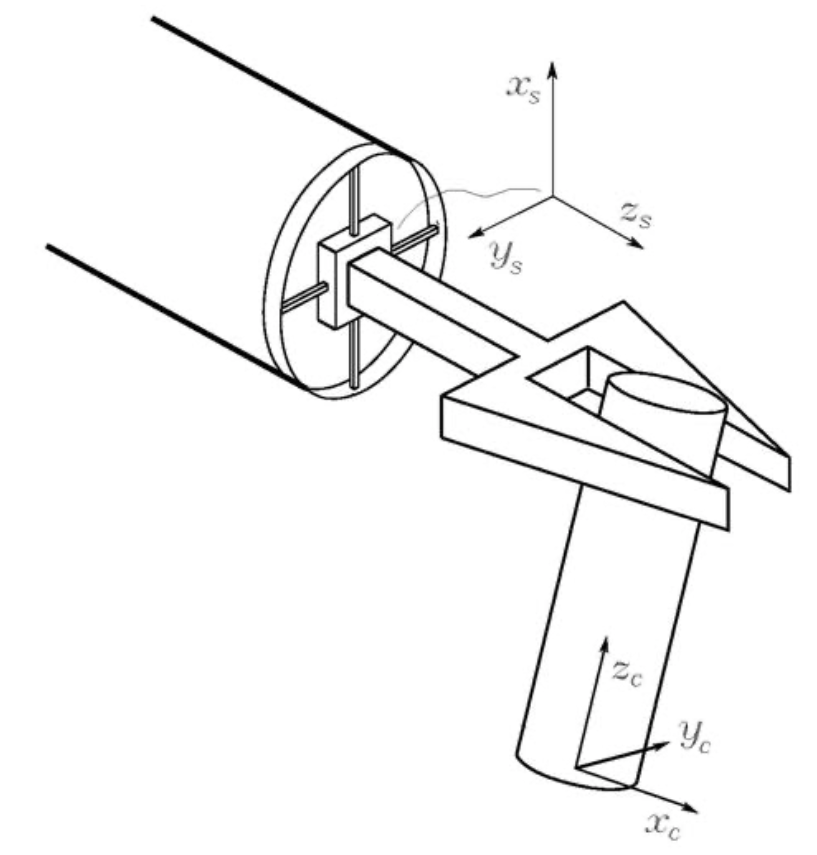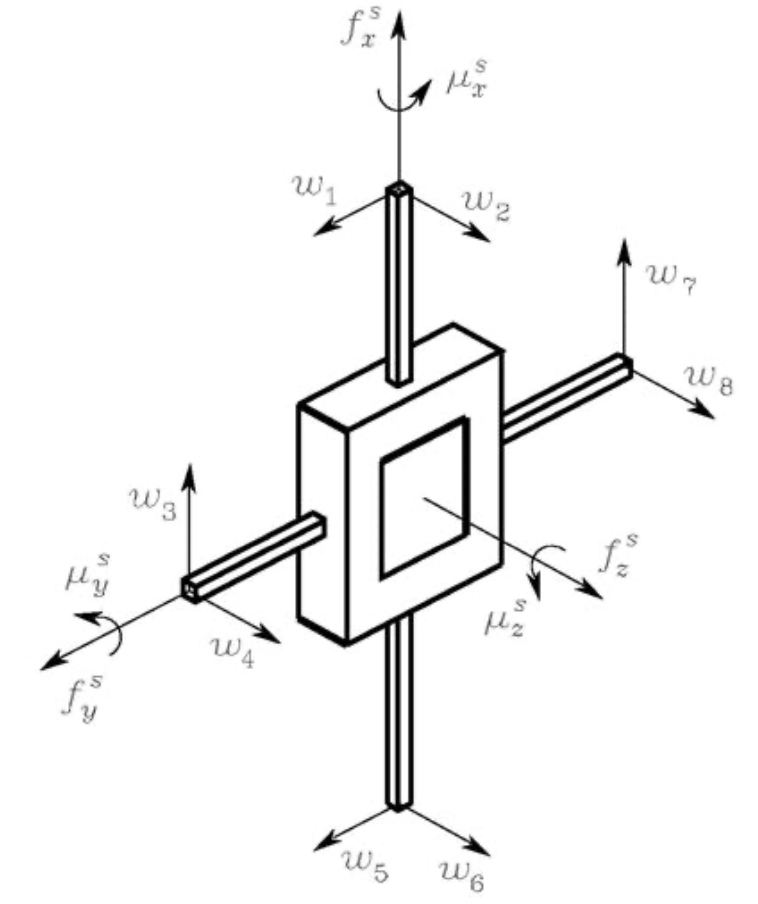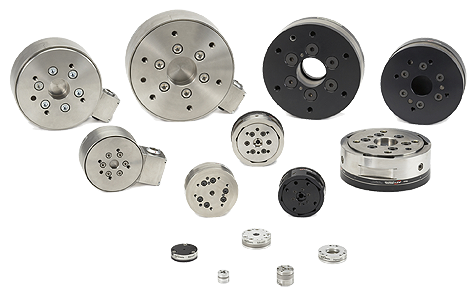

syms f_sx f_sy f_sz mu_sx mu_sy mu_sz c_13 c_17 c_12 c_25 c_32 c_34 c_36 c_38 c_44 c_48 c_52 c_56 c_61 c_63 c_65 c_67
syms w_1 w_2 w_3 w_4 w_5 w_6 w_7 w_8 % output of Weatstone bridges

[f_sx f_sy f_sz mu_sx mu_sy mu_sz]'==[0 0 c_13 0 0 0 c_17 0,
    c_12 0 0 0 c_25 0 0 0,
    0 c_32 0 c_34 0 c_36 0 c_38,
    0 0 0 c_44 0 0 0 c_48,
    0 c_52 0 0 0 c_56 0 0,
    c_61 0 c_63 0 c_65 0 c_67 0]*[w_1 w_2 w_3 w_4 w_5 w_6 w_7 w_8]'

$$ans = \left(\begin{array}{c} \bar{f_{\mathrm{sx}}}=c_{13}\,\bar{w_{3}}+c_{17}\,\bar{w_{7}}\\ \bar{f_{\mathrm{sy}}}=c_{12}\,\bar{w_{1}}+c_{25}\,\bar{w_{5}}\\ \bar{f_{\mathrm{sz}}}=c_{32}\,\bar{w_{2}}+c_{34}\,\bar{w_{4}}+c_{36}\,\bar{w_{6}}+c_{38}\,\bar{w_{8}}\\ \bar{\mu_{\mathrm{sx}}}=c_{44}\,\bar{w_{4}}+c_{48}\,\bar{w_{8}}\\ \bar{\mu_{\mathrm{sy}}}=c_{52}\,\bar{w_{2}}+c_{56}\,\bar{w_{6}}\\ \bar{\mu_{\mathrm{sz}}}=c_{61}\,\bar{w_{1}}+c_{63}\,\bar{w_{3}}+c_{65}\,\bar{w_{5}}+c_{67}\,\bar{w_{7}} \end{array}\right)$$


syms f_c mu_c R_cs f_s mu_s r_ccs

[f_c mu_c]'== [R_cs 0,
    r_ccs*R_cs R_cs]*[f_s mu_s]'

$$ans = \left(\begin{array}{c} \bar{f_{c}}=R_{\mathrm{cs}}\,\bar{f_{s}}\\ \bar{\mu_{c}}=R_{\mathrm{cs}}\,\bar{\mu_{s}}+R_{\mathrm{cs}}\,r_{\mathrm{ccs}}\,\bar{f_{s}} \end{array}\right)$$

PASSIVE RCC DEVICE - (REMOTE CENTER OF COMPLIANCE)

PROXIMITY INFRARED / ULTRASOUND / LASER SCANNER / STRUCTURED LIGHT SENSOR - (DISTANCE)

CCD (CHARGE COUPLED DEVICE) / 	CMOS (COMPLEMENTARY METAL OXIDE SEMICONDUCTOR) - (VISION)

PERSPECTIVE TRANSFORMATION MATRICES 